# Esperimento didattico di misure meccaniche e termiche - Acquisizione dati da esercizi di un allenamento sportivo.

L'attività didattica ha lo scopo di utilizzare il comune smartphone per svolgere delle acquisizioni relative al segnale di accelerazione durante lo svolgimento di specifiche azioni.

Nello specifico, vengono acquisiti i dati di accelerazione lungo le 3 componenti x,y e z mentre si svolgono 4 diverse attività. In particolare, queste attività sono relative a 4** diversi esercizi svolti durante un workout a corpo libero.**

Sarà necessario analizzare i dati nel dominio del tempo e della frequenza per evidenziare le caratteristiche del segnale che vogliamo analizzare. Tali features dovranno successivamente essere utilizzare per addestrare un classificatore in grado di distinguere le diverse azioni.

## Caricamento dei dati

Il file risultante dall'acquisizione con smartphone contiene i valori di accelerazione lungo le componenti x,y e z ed uno timestamp riportante la data e l'ora di acquisizione.

Comunemente gli assi relativi al sensore di accelerazione all'interno dello smartphone sono orientati come in figura:

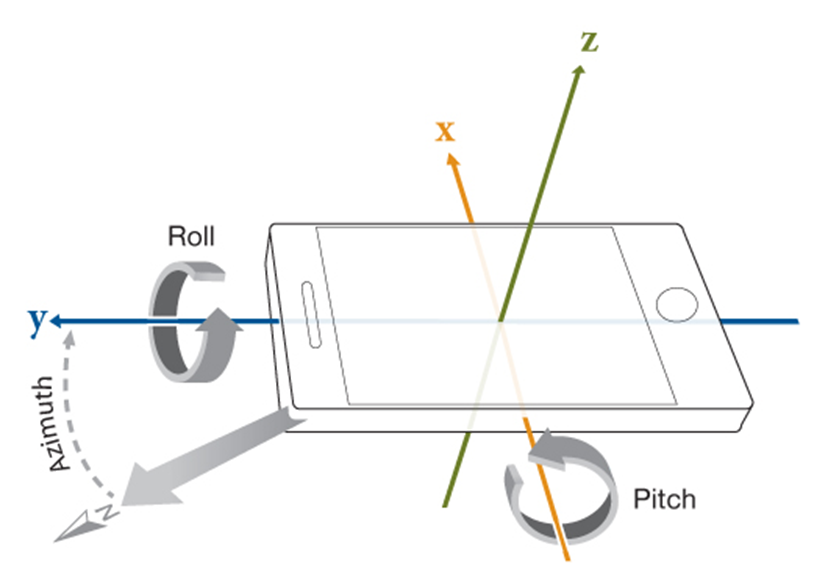

Ad ogni attività è stato assegnato un codice univoco:

**            1  = Flessioni **

**            2 = Jumping Jacks**

**            3 = Addominali Obliqui**

**            4 = Burpees**

•  *fs* è la frequenza di campionamento ed è pari a **50** Hz

clear 
close
clc

fs = 50;

% Funzione per unire i vari set di dati e caricarli nel Workspace
[flessioni,jumping_jacks,obliqui,burpees] = unione()

flessioni = 6389×3 timetable
           Timestamp                X          Y          Z   
    ________________________    _________    ______    _______

    23-May-2022 14:05:06.377     -0.51735    3.7164    -8.9312
    23-May-2022 14:05:06.396    -0.071357    3.2713    -8.9558
    23-May-2022 14:05:06.415    -0.096075    2.7732    -9.5974
    23-May-2022 14:05:06.434      -0.3093    2.6685    -9.2237
    23-May-2022 14:05:06.453     -0.35001     3.048    -9.1837
    23-May-2022 14:05:06.472     -0.33927    3.2876         -9
    23-May-2022 14:05:06.491     -0.15643    3.2256    -9.3866
    23-May-2022 14:05:06.510     -0.12051    3.0851    -9.3534
    23-May-2022 14:05:06.529     -0.28001    3.0766

jumping_jacks = 6972×3 timetable
           Timestamp               X         Y         Z   
    ________________________    _______    ______    ______

    23-May-2022 14:00:04.439    0.79407    8.7538    2.2183
    23-May-2022 14:00:04.458    0.69824    9.4371    2.4179
    23-May-2022 14:00:04.477    0.75125    9.9007    2.3464
    23-May-2022 14:00:04.496    0.60348    10.078    2.0909
    23-May-2022 14:00:04.515    0.68942    9.8328    2.1732
    23-May-2022 14:00:04.534    0.57594    9.4789    2.3861
    23-May-2022 14:00:04.553    0.29742    9.4807    2.4348
    23-May-2022 14:00:04.572    0.35318    9.8146    2.2309
    23-May-2022 14:00:04.591     0.4973    10.023    1.9865
    23-Ma

obliqui = 5555×3 timetable
           Timestamp               X          Y         Z   
    ________________________    ________    ______    ______

    23-May-2022 15:06:40.186    -0.12609    8.2474    4.0949
    23-May-2022 15:06:40.205    -0.58898    8.2352    4.1007
    23-May-2022 15:06:40.224     -1.3247    8.9922    4.2296
    23-May-2022 15:06:40.243     -1.0209    9.6382    4.3177
    23-May-2022 15:06:40.262    -0.43953    10.063    4.1952
    23-May-2022 15:06:40.281    -0.35312    9.4897    4.0969
    23-May-2022 15:06:40.300    -0.46987    9.4055    4.2068
    23-May-2022 15:06:40.319    -0.61721    8.9164    4.1369
    23-May-2022 15:06:40.338    -0.75626    8.7481    3.9689
    

burpees = 4768×3 timetable
           Timestamp                X          Y           Z    
    ________________________    _________    ______    _________

    23-May-2022 14:58:51.038      0.30639    9.8972     -0.28827
    23-May-2022 14:58:51.057      0.32695     9.968     -0.26911
    23-May-2022 14:58:51.076      0.22415    9.9585     -0.44778
    23-May-2022 14:58:51.095      0.27217    9.9489     -0.45808
    23-May-2022 14:58:51.114      0.33591    9.8935     -0.52841
    23-May-2022 14:58:51.133      0.28689    9.8248     -0.23871
    23-May-2022 14:58:51.152      0.11055    10.002    -0.069499
    23-May-2022 14:58:51.171     -0.26721    10.126     -0.61965
    23-May-2022 14:58:51.190     


% funzione per convertire le timetable in array
[fl,jj,o,b] = setup(flessioni,jumping_jacks,obliqui,burpees);

activity = {fl,jj,o,b}

activity = 1×4 cell array
    {6389×3 double}    {6972×3 double}    {5555×3 double}    {4768×3 double}


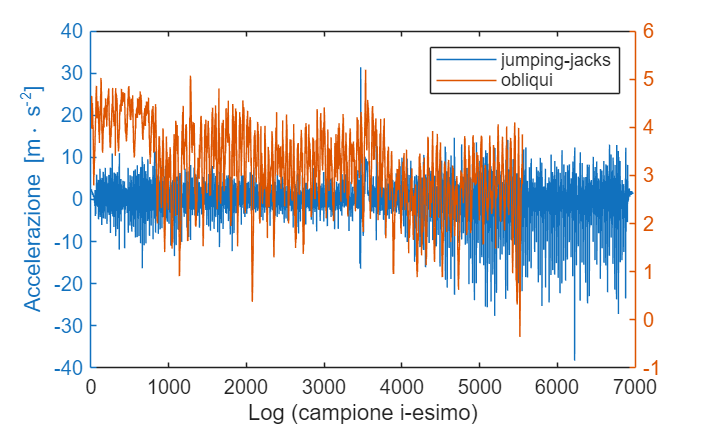

activities = {'flessioni'  'jumping-jacks'  'obliqui'  'burpees'};
scelta_attiv1 = 2;
scelta_attiv2 = 3;
asse = 3;

figure, yyaxis left, plot(activity{scelta_attiv1}(:,asse))
ylabel('Accelerazione [m\cdot s^{-2}]')
xlabel('Log (campione i-esimo)')
hold on
yyaxis right, plot(activity{scelta_attiv2}(:,asse))
legend ([cellstr(activities(scelta_attiv1)) cellstr(activities(scelta_attiv2))])
hold off

## Istogramma

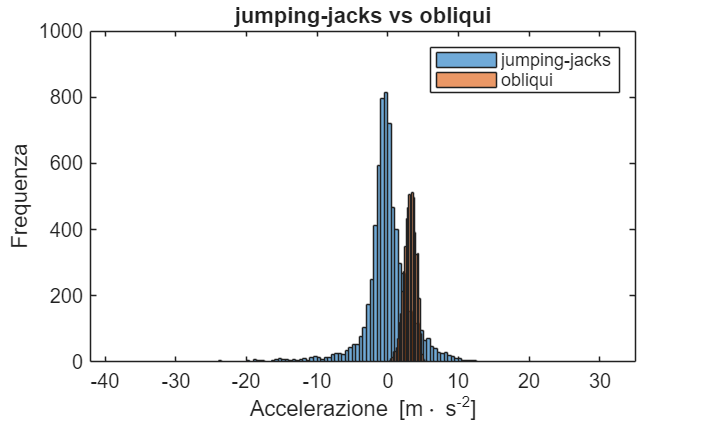

% Seleziono solamente i dati di interesse
figure
histogram(activity{scelta_attiv1}(:,asse))
hold on
histogram(activity{scelta_attiv2}(:,asse))
hold off
legend ([cellstr(activities(scelta_attiv1)) cellstr(activities(scelta_attiv2))]);
xlabel('Accelerazione [m\cdot s^{-2}]')
ylabel('Frequenza')
title (strcat(activities(scelta_attiv1), " vs ", activities(scelta_attiv2)))

## Riorganizzazione dati

I dati sono stati riorganizzati in modo da avere ciascuna azione suddivisa in **n** set (campioni statistici) in riga ciascuna da **150** dati campionati. Ciascun set è un campione statistico.

Tanti set serviranno  per **allenare il classificatore**!

I dati sono salvati nel file "Dati" e sono organizzati in una Cell Array di 6 elementi:

**            Posizione 1 = Flessioni**

**            Posizione 2 = Jumping jacks**

**            Posizione 3 = Obliqui**

**            Posizione 4 = Burpees**

Le tre componenti realizzano ciascuna una matrice nx150. Quindi ogni elemento del Cell Array è organizzato in forma di matrice 3D con dimensioni (*n x 150 x 3*) come in figura:

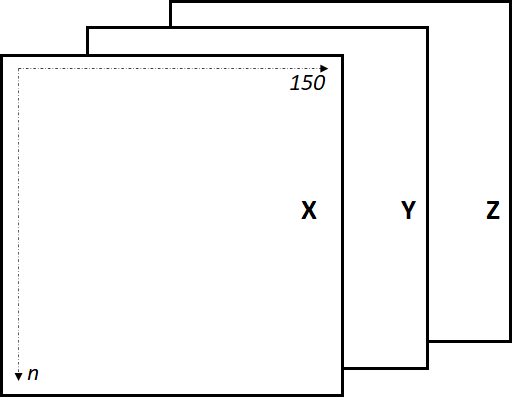

I dati tramite la funzione riorganizza_dati vengono riorganizzani in set di 150 campioni

FL = riorganizza_datiB(fl);
JJ = riorganizza_datiB(jj);
OO = riorganizza_datiB(o);
BB = riorganizza_datiB(b);

Dati = {FL,JJ,OO,BB} %creazione dell cell array contenenti le varie azioni

Dati = 1×4 cell array
    {43×150×3 double}    {47×150×3 double}    {38×150×3 double}    {32×150×3 double}


Di seguito un **esempio** su come estrarre i diversi campioni statistici per ciascuna azione:

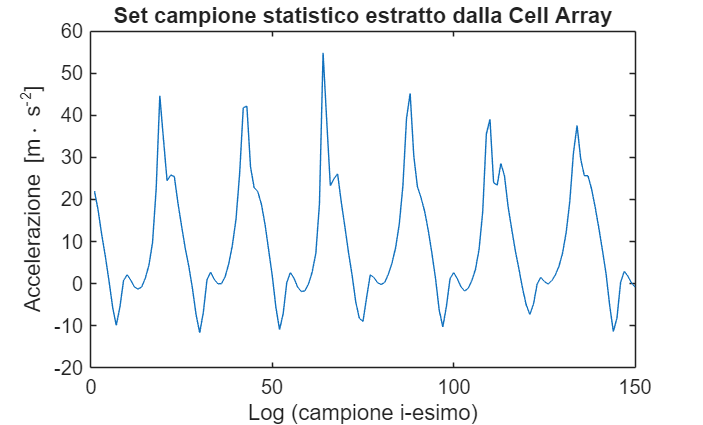

activity_ID = 2;
component1 = 2;
sample_Number = 3;
sampleStat = Dati{activity_ID}(sample_Number,:,component1);
figure
plot(sampleStat)
title('Set campione statistico estratto dalla Cell Array')
ylabel('Accelerazione [m\cdot s^{-2}]')
xlabel('Log (campione i-esimo)')

## Analisi in frequenza

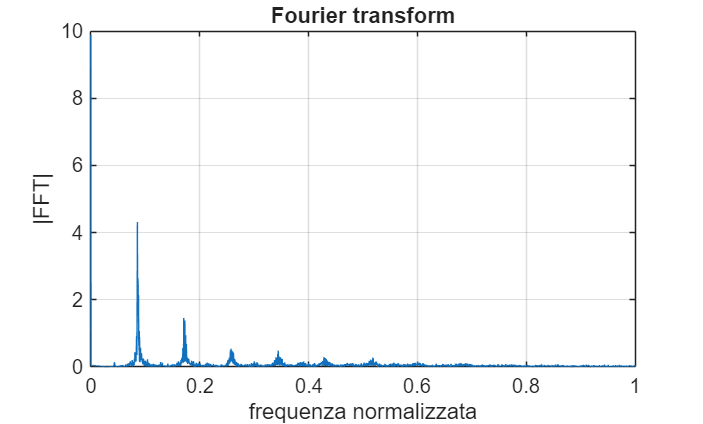

activity_fft = 2;
component2 = 2;

acceleration_filt = activity{activity_fft}(:,component2);
figure
Plot_FFT(acceleration_filt, fs);

Confronto tra spettri di azioni differenti:

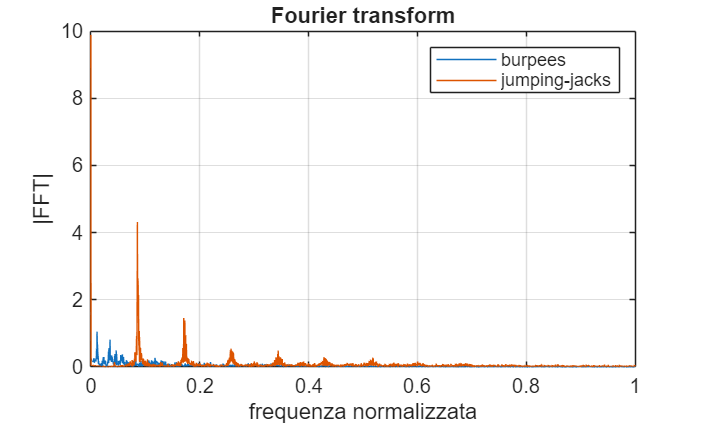

activity_one_fft = 4;
activity_two_fft = 2;

% Seleziono lo stato di interesse :
figure
acceleration_filt = activity{activity_one_fft}(:,component2);
Plot_FFT(acceleration_filt, fs);
hold on

% Seleziono secondo stato di interesse :
acceleration_s = activity{activity_two_fft}(:,component2);
Plot_FFT(acceleration_s, fs);
hold off
legend ([cellstr(activities(activity_one_fft)) cellstr(activities(activity_two_fft))])

## Filtraggio

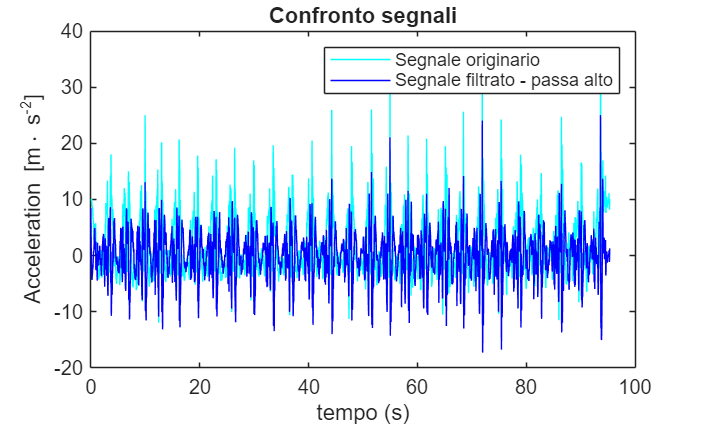

%Disegno del filtro passa basso per eliminare la componente continua
Filter_order1 =5;
tau1 = 0.03;

[B, A] = Filtro_high(acceleration_filt, fs,Filter_order1,tau1);

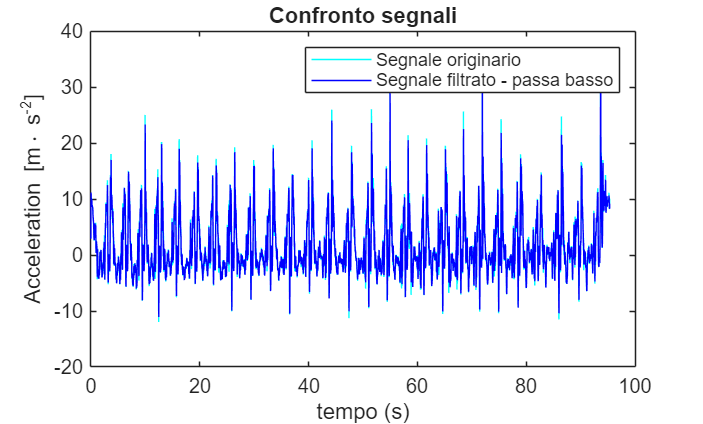

%fvtool(B,A)


%Disegno del filtro passa alto per eliminare la componente ad alta
%frequenza data la natura degli esercizi
Filter_order2 =2;
tau2 = 0.5;
[D, C] = Filtro_low(acceleration_filt, fs,Filter_order2,tau2);

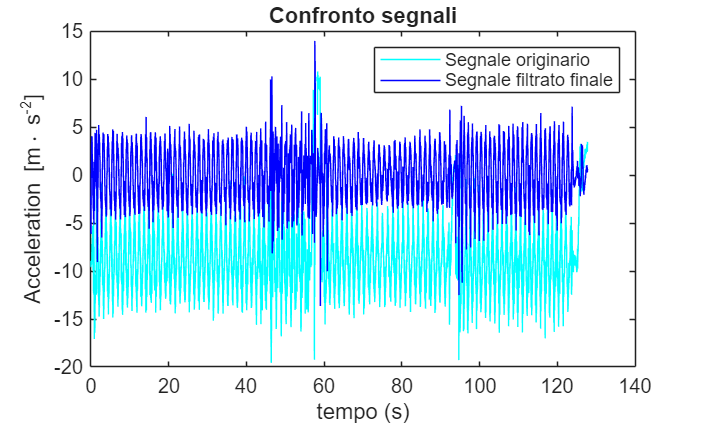

%fvtool(D,C)


%segnale finale filtrato

activity_tobefiltered = 1;
componenT_tobefiltered = 3;

acceleration_tobefiltered = activity{activity_tobefiltered}(:,componenT_tobefiltered);

FiltroB(acceleration_tobefiltered,fs,A,B,C,D)

## FUNZIONE PER RICAVARE LE FEATURES

Nello step di estrazione delle features viene generata una funzione responsabile del salvataggio delle caratteristiche fondamentali del segnale, che verranno successivamente utilizzate per la classificazione.

- Media del segnale

- Deviazione standard del segnale

- Valore del picco principale della FFT del segnale

- Posizione del picco principale della FFT del segnale

INPUT: 

- Cell Array [stat_c]

- Frequenza di campionamento [fs]

- A, B,  dei filtri prima ricavati (serve per calcolare la deviazione standard in modo più accurato)

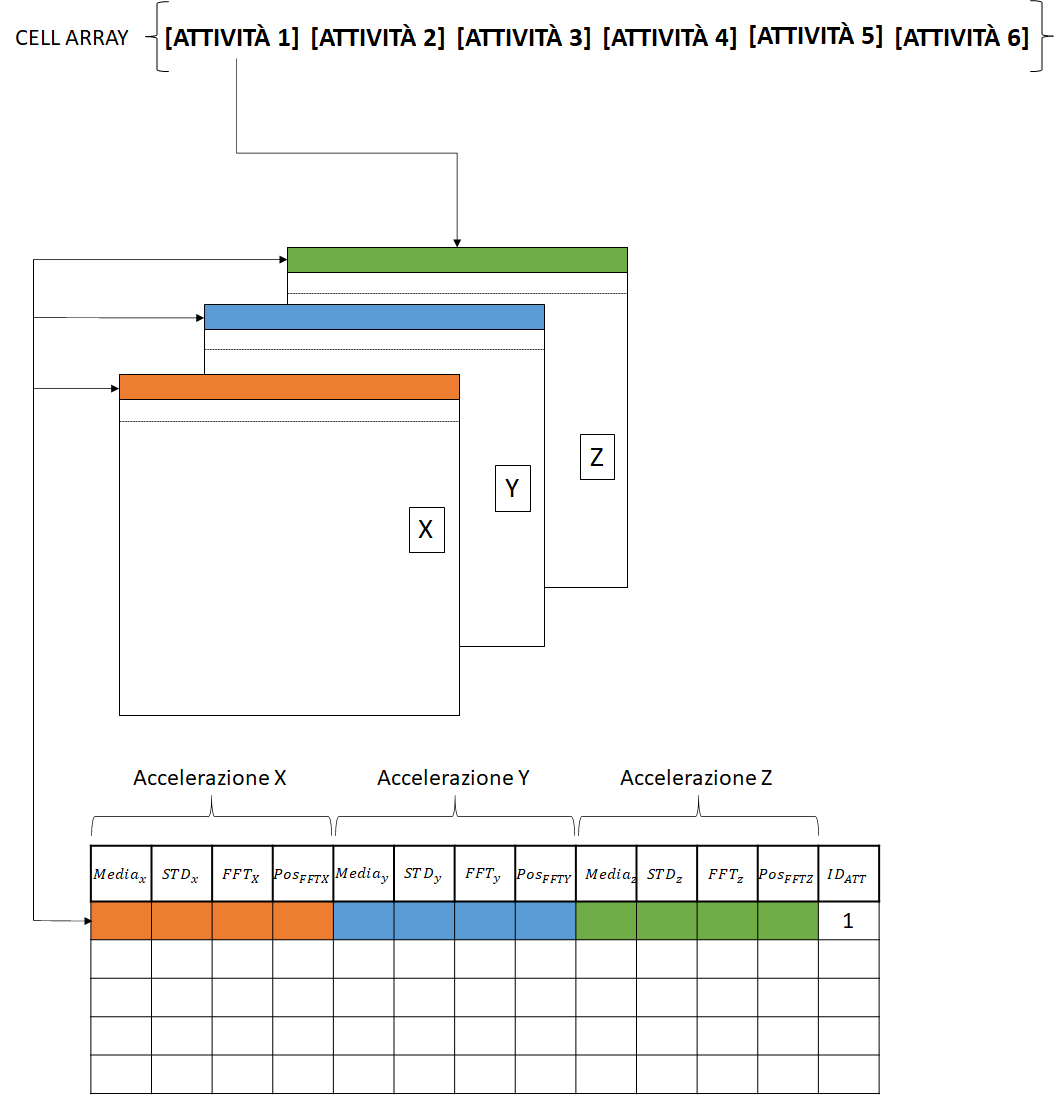

### **Estrazione delle features**

features = ExtractSignalFeatures2(Dati, fs, A, B, C, D);
featlabels = {'Media x', 'STD x', 'ampiezza picco FFT x', 'posizione picco FFT x','Media 6 picchi x','Posizione media 6 picchi x','Differenza picchi x', 'Media y', 'STD y', 'ampiezza picco FFT y', 'posizione picco FFT y','Media 6 picchi y','Posizione media 6 picchi y','Differenza picchi y', 'Media z', 'STD z', 'ampiezza picco FFT z', 'posizione picco FFT z','Media 6 picchi z','Posizione media 6 picchi z','Differenza picchi z','Activity ID'};

## ALGORITMO DI CLASSIFICAZIONE

In questa fase viene realizzato il classificatore, partendo dalle features precedentemente estratte.

E' necessario realizzare una tabella per importare i dati nell'algoritmo di classificazione.

featT = array2table(features, 'VariableNames',featlabels); % tabella della features

## PREVISIONE

Test del modello su dati acquisiti tramite smartphone.

**1.    Suddividere il set di dati in due campioni:**

- 80% dei dati (scelti casualmente): TRAINING

- 20% dei dati: TEST

**2.    Realizzare il modello per la previsione delle 6 attività **(utilizzare i dati di training) 

%activity2=activity %per non farla variare
[train,test,activity_guess] = prevision2(features);

featT_train = array2table(train, 'VariableNames',featlabels);
featlabels_new = {'Media x', 'STD x', 'ampiezza picco FFT x', 'posizione picco FFT x','Media 6 picchi x','Posizione media 6 picchi x','Differenza picchi x', 'Media y', 'STD y', 'ampiezza picco FFT y', 'posizione picco FFT y','Media 6 picchi y','Posizione media 6 picchi y','Differenza picchi y', 'Media z', 'STD z', 'ampiezza picco FFT z', 'posizione picco FFT z','Media 6 picchi z','Posizione media 6 picchi z','Differenza picchi z'}

featlabels_new = 1×21 cell array
    {'Media x'}    {'STD x'}    {'ampiezza picco FFT x'}    {'posizione picco FFT x'}    {'Media 6 picchi x'}    {'Posizione media 6 picchi x'}    {'Differenza picchi x'}    {'Media y'}    {'STD y'}    {'ampiezza picco FFT y'}    {'posizione picco FFT y'}    {'Media 6 picchi y'}    {'Posizione media 6 picchi y'}    {'Differenza picchi y'}    {'Media z'}    {'STD z'}    {'ampiezza picco FFT z'}    {'posizione picco FFT z'}    {'Media 6 picchi z'}    {'Posizione media 6 picchi z'}    {'Differenza picchi z'}


featT_test = array2table(test, 'VariableNames',featlabels_new);
classificationLearner

**3.    Testare il modello **(utilizzare i dati di test)

predictions = trainedModel.predictFcn(featT_test);

**4.    Visualizzare la confusion matrix **

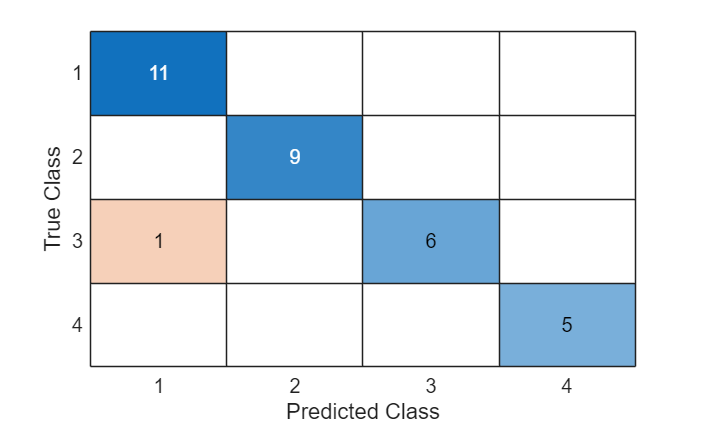

confusionchart(activity_guess,predictions)